# Fixed-Point Addition

Whenever you add two fixed-point numbers, you may need a carry bit to correctly represent the result. For this reason, when adding two B-bit numbers (with the same scaling), the resulting value has an extra bit compared to the two operands used.

The addition of fixed-point numbers requires that the binary points of the addends be aligned. The addition is then performed using binary arithmetic so that no number other than 0 or 1 is used.

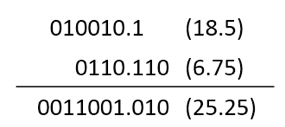

In the following example, note that the sum, $c$, of $a$ and $b$ has a word length (10) equal to one greater than the sum of the largest input fraction length (3), and the largest input integer length ($7-1 = 6$).

a = fi(18.5,0,7,1)
a.bin

b = fi(6.75,0,7,3)
b.bin

c = a + b
c.bin

## C code generation

codegen myplus -args {a,b} -config:lib -launchreport

## HDL code generation

codegen myplus -args {a,b} -config:hdl -launchreport

## SystemC code generation

cfg = coder.HdlConfig;
cfg.TargetLanguage = "SystemC";
codegen myplus -args {a,b} -config cfg -launchreport